# **Fase 1: Modelado y caracterización de la planta en lazo abierto**

### **Ejercicio 1: Obtener la FdeT de la planta en lazo abierto.**

Después de realizar capturas del dispositivo con diferentes valores de entrada escalón, obtenemos la km y Tau de cada salida:

- Cargar el archivo .txt con los valores capturados.

- Representar la entrada escalón y la respuesta de la planta en lazo abierto.

- Recortar la señal de saliida.

- Ajustar la señal a 5 segundos.

- Hallar la km: Mediante la media de las últimas muestras.

- Hallar la Tau: Instante del tiempo en el que la señal vale el 63.2% de la km.

clear
addpath('Funciones\');
addpath('Simulink\')

format long
Ts = 35e-3;
fprintf('El periodo de muestreo es: %.4f s.\n', Ts)

El periodo de muestreo es: 0.0350 s.


**Entrada escalón 1V:**

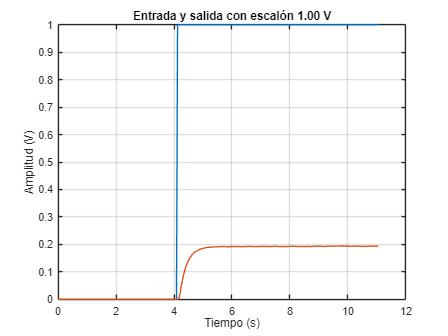

[salida_1V, tiempo_1V] = representar('./Capturas/Fase1/PGA_G4_1V.txt', 1, 'V', 0);

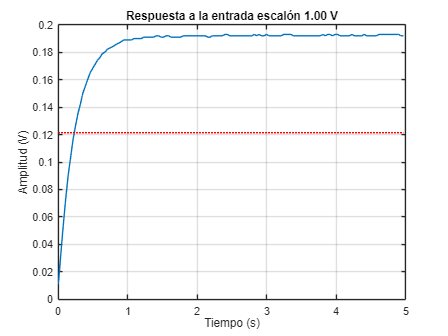

[km_1V, Tau_1V, salida_1V, tiempo_1V] = salida(salida_1V, tiempo_1V, Ts, 1, 'V', 0);

fprintf('km con entrada escalón de 1V: %.4f.\n', km_1V)

km con entrada escalón de 1V: 0.1920.


fprintf('Tau con entrada escalón de 1V: %.4f s.\n', Tau_1V)

Tau con entrada escalón de 1V: 0.2625 s.


**Entrada escalón 2V:**

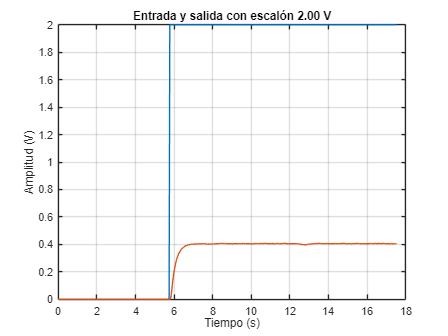

[salida_2V, tiempo_2V] = representar('./Capturas/Fase1/PGA_G4_2V.txt', 2, 'V', 0);

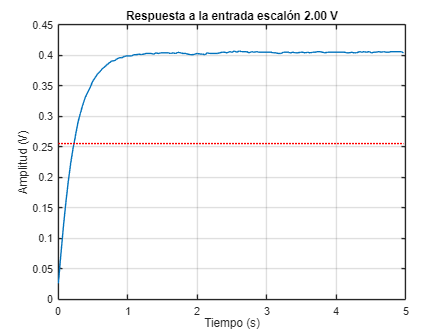

[km_2V, Tau_2V, salida_2V, tiempo_2V] = salida(salida_2V, tiempo_2V, Ts, 2, 'V', 0);

fprintf('km con entrada escalón de 2V: %.4f.\n', km_2V)

km con entrada escalón de 2V: 0.2030.


fprintf('Tau con entrada escalón de 2V: %.4f s.\n', Tau_2V)

Tau con entrada escalón de 2V: 0.2625 s.


**Entrada escalón 5V:**

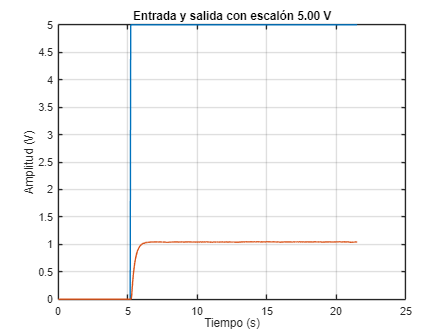

[salida_5V, tiempo_5V] = representar('./Capturas/Fase1/PGA_G4_5V.txt', 5, 'V', 0);

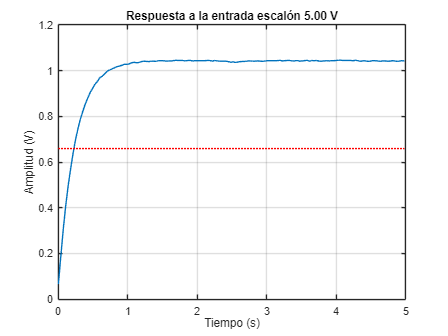

[km_5V, Tau_5V, salida_5V, tiempo_5V] = salida(salida_5V, tiempo_5V, Ts, 5, 'V', 0);

fprintf('km con entrada escalón de 5V: %.4f.\n', km_5V)

km con entrada escalón de 5V: 0.2079.


fprintf('Tau con entrada escalón de 5V: %.4f s.\n', Tau_5V)

Tau con entrada escalón de 5V: 0.2625 s.


**Entrada escalón -1V:**

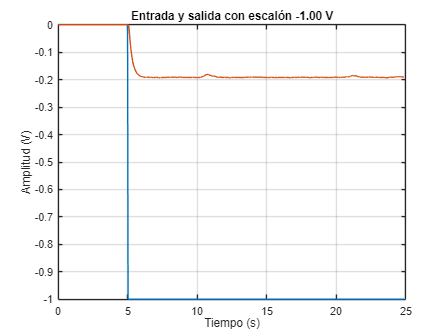

[salida_n1V, tiempo_n1V] = representar('./Capturas/Fase1/PGA_G4_n1V.txt', -1, 'V', 0);

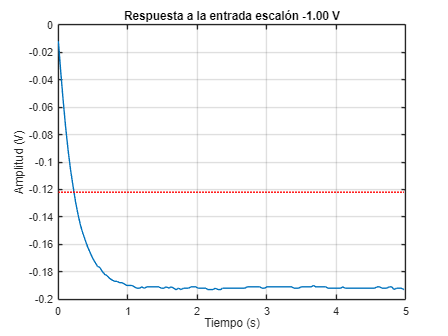

[km_n1V, Tau_n1V, salida_n1V, tiempo_n1V] = salida(salida_n1V, tiempo_n1V, Ts, -1, 'V', 0);

fprintf('km con entrada escalón de -1V: %.4f.\n', km_n1V)

km con entrada escalón de -1V: 0.1925.


fprintf('Tau con entrada escalón de -1V: %.4f s.\n', Tau_n1V)

Tau con entrada escalón de -1V: 0.2625 s.


**Entrada escalón -2V:**

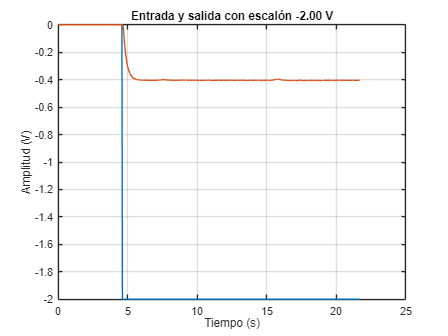

[salida_n2V, tiempo_n2V] = representar('./Capturas/Fase1/PGA_G4_n2V.txt', -2, 'V', 0);

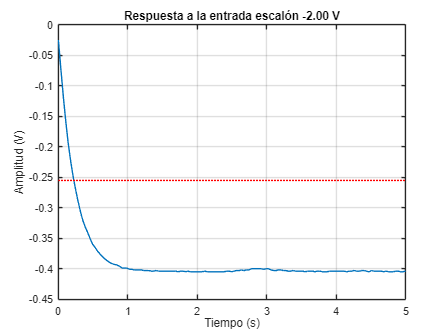

[km_n2V, Tau_n2V, salida_n2V, tiempo_n2V] = salida(salida_n2V, tiempo_n2V, Ts, -2, 'V', 0);

fprintf('km con entrada escalón de -2V: %.4f.\n', km_n2V)

km con entrada escalón de -2V: 0.2023.


fprintf('Tau con entrada escalón de -2V: %.4f s.\n', Tau_n2V)

Tau con entrada escalón de -2V: 0.2625 s.


**Entrada escalón -5V:**

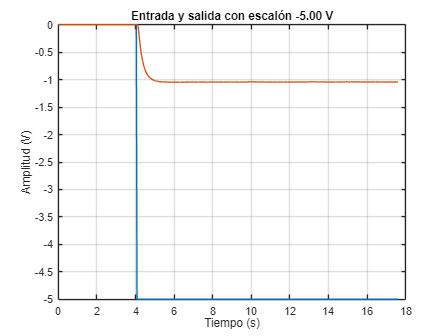

[salida_n5V, tiempo_n5V] = representar('./Capturas/Fase1/PGA_G4_n5V.txt', -5, 'V', 0);

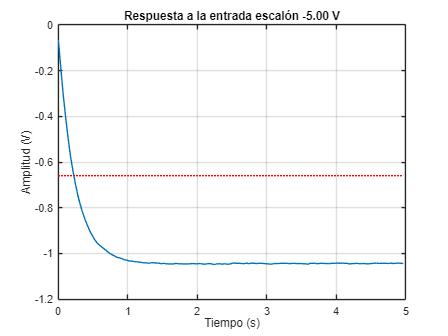

[km_n5V, Tau_n5V, salida_n5V, tiempo_n5V] = salida(salida_n5V, tiempo_n5V, Ts, -5, 'V', 0);

fprintf('km con entrada escalón de -5V: %.4f.\n', km_n5V)

km con entrada escalón de -5V: 0.2087.


fprintf('Tau con entrada escalón de -5V: %.4f s.\n', Tau_n5V)

Tau con entrada escalón de -5V: 0.2625 s.


Después, hacemos la media de las kms y Taus para obtener de forma más precisa la km y Tau del sistema:

km = mean([km_1V (km_2V) (km_5V) (km_n1V) (km_n2V) (km_n5V)]);
Tau = mean([Tau_1V Tau_2V Tau_5V Tau_n1V Tau_n2V Tau_n5V]);

fprintf('La km de la planta es: %.4f.\n', km)

La km de la planta es: 0.2011.


fprintf('La Tau de la planta es: %.4f s.\n', Tau)

La Tau de la planta es: 0.2625 s.


Finalmente, sustituimos para obtener la FdeT de la planta:

Gs = tf(km, [Tau 1]);


$$G(s) = \frac{km}{Tau \cdot s + 1} = \frac{0.2011}{0.2625s + 1} [\frac{m/s}{V}]$$


p = pole(Gs);
fprintf('El polo de la planta es: %.4f.\n', p)

El polo de la planta es: -3.8095.


ts = -3/p;
fprintf('El tiempo de establecimiento de la planta es: %.4f.\n', ts)

El tiempo de establecimiento de la planta es: 0.7875.


### Ejercicio 2: Validar el modelo mediante Simulink.

Comprobar que para todas las capturas realizadas, el modelo coincide con el valor obtenido:

**Entrada escalón 1V:**

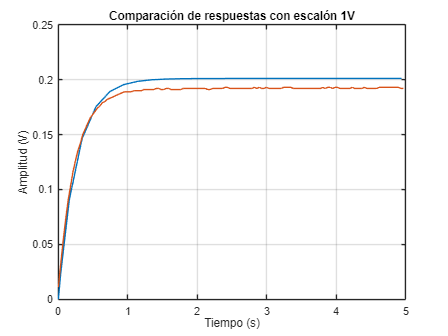

step_value = 1;
[salida_simulado, tiempo_simulado] = simulink('modeloFdeT', '10');
comparacion(salida_simulado,tiempo_simulado,salida_1V,tiempo_1V,'null','null','Comparación de respuestas con escalón 1V')

**Entrada escalón -1V:**

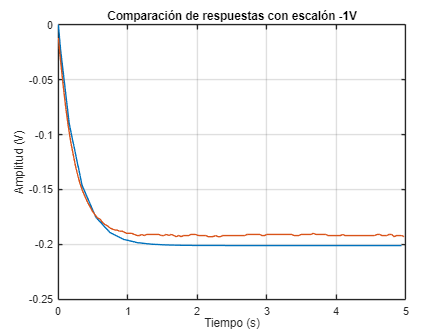

step_value = -1;
[salida_simulado, tiempo_simulado] = simulink('modeloFdeT', '10');
comparacion(salida_simulado,tiempo_simulado,salida_n1V,tiempo_n1V,'null','null','Comparación de respuestas con escalón -1V')

**Entrada escalón 2V:**

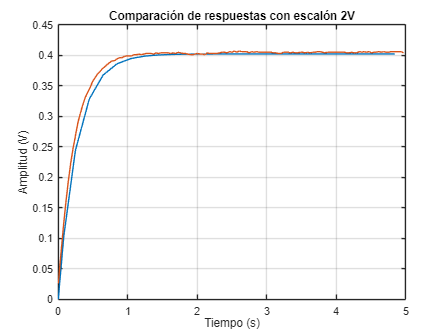

step_value = 2;
[salida_simulado, tiempo_simulado] = simulink('modeloFdeT', '10');
comparacion(salida_simulado,tiempo_simulado,salida_2V,tiempo_2V,'null','null','Comparación de respuestas con escalón 2V')

**Entrada escalón -2V:**

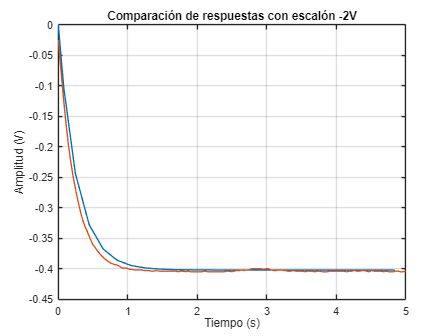

step_value = -2;
[salida_simulado, tiempo_simulado] = simulink('modeloFdeT', '10');
comparacion(salida_simulado,tiempo_simulado,salida_n2V,tiempo_n2V,'null','null','Comparación de respuestas con escalón -2V')

**Entrada escalón 5V:**

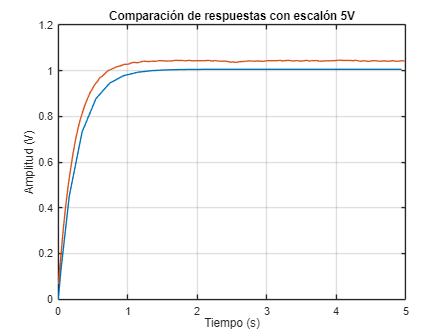

step_value = 5;
[salida_simulado, tiempo_simulado] = simulink('modeloFdeT', '10');
comparacion(salida_simulado,tiempo_simulado,salida_5V,tiempo_5V,'null','null','Comparación de respuestas con escalón 5V')

**Entrada escalón -5V:**

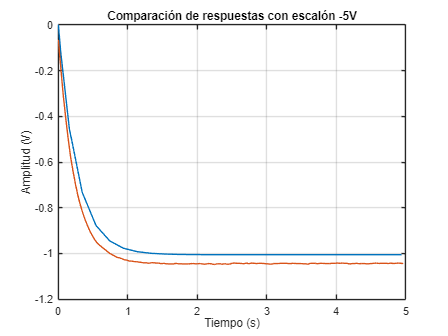

step_value = -5;
[salida_simulado, tiempo_simulado] = simulink('modeloFdeT', '10');
comparacion(salida_simulado,tiempo_simulado,salida_n5V,tiempo_n5V,'null','null','Comparación de respuestas con escalón -5V')

### Ejercicio 3: Modelación de la saturación y la zona muerta.

#### Saturación: 

Se produce a partir de entrada escalón ≥ ±10V.

**Saturación positiva:**

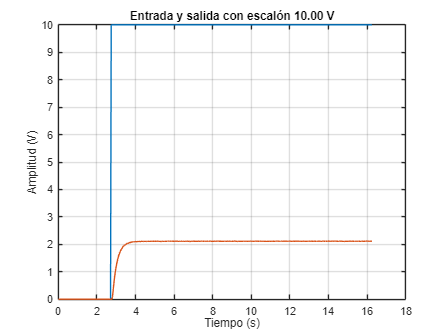

[salida_10V, tiempo_10V] = representar('./Capturas/Fase1/PGA_G4_10V.txt', 10, 'V', 0);

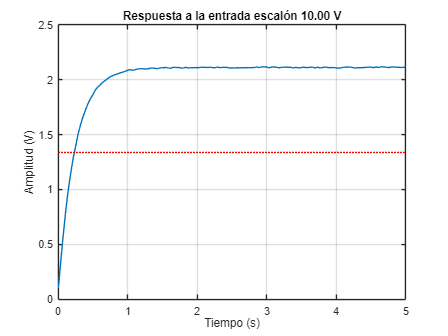

[km_10V, Tau_10V, salida_10V, tiempo_10V] = salida(salida_10V, tiempo_10V, Ts, 10, 'V', 0);

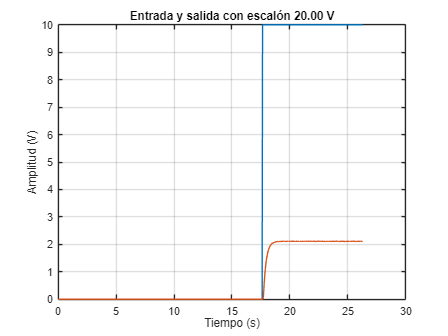

[salida_20V, tiempo_20V] = representar('./Capturas/Fase1/PGA_G4_20V.txt', 20, 'V', 0);

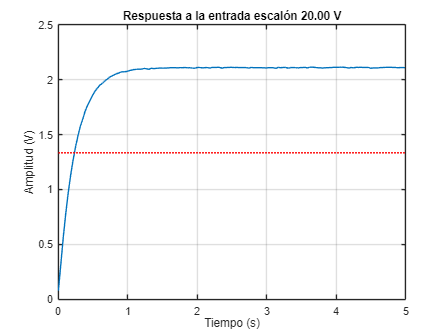

[km_20V, Tau_20V, salida_20V, tiempo_20V] = salida(salida_20V, tiempo_20V, Ts, 20, 'V', 0);

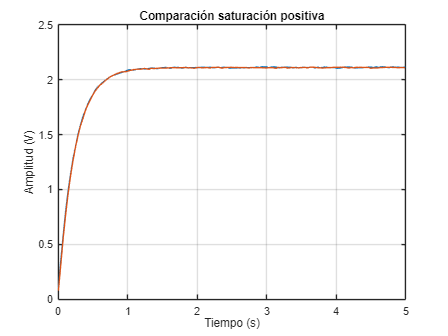

comparacion(salida_10V,tiempo_10V,salida_20V,tiempo_20V,'null','null','Comparación saturación positiva')

fprintf('Salida saturada positiva: %.4f.\n', (km_10V*10 + km_20V*20)/2)

Salida saturada positiva: 2.1098.


**Saturación negativa:**

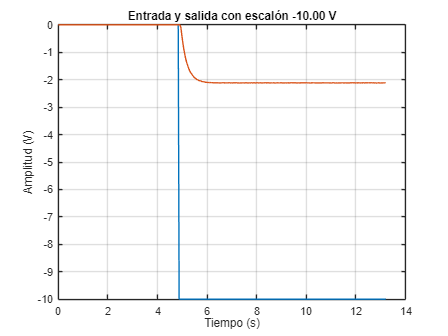

[salida_n10V, tiempo_n10V] = representar('./Capturas/Fase1/PGA_G4_n10V.txt', -10, 'V', 0);

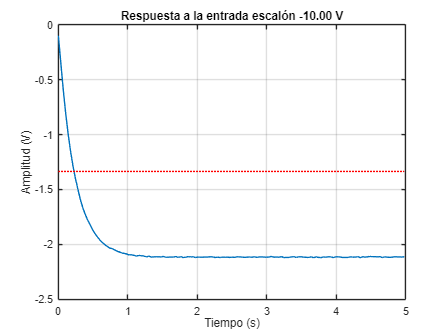

[km_n10V, Tau_n10V, salida_n10V, tiempo_n10V] = salida(salida_n10V, tiempo_n10V, Ts, -10, 'V', 0);

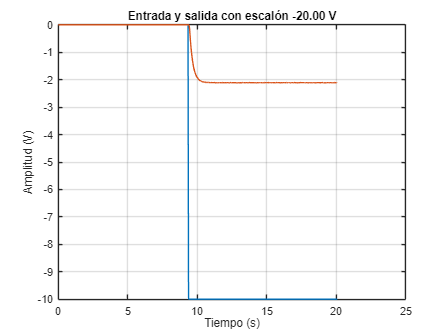

[salida_n20V, tiempo_n20V] = representar('./Capturas/Fase1/PGA_G4_n20V.txt', -20, 'V', 0);

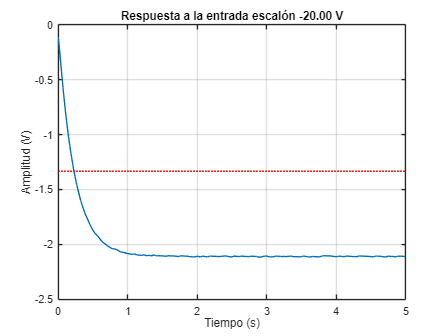

[km_n20V, Tau_n20V, salida_n20V, tiempo_n20V] = salida(salida_n20V, tiempo_n20V, Ts, -20, 'V', 0);

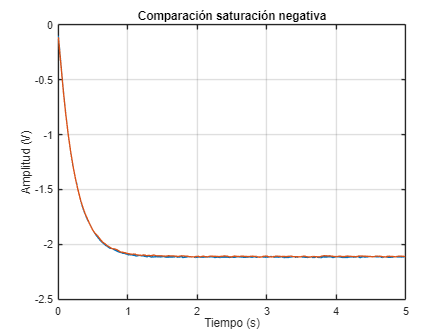

comparacion(salida_n10V,tiempo_n10V,salida_n20V,tiempo_n20V,'null','null','Comparación saturación negativa')

fprintf('Salida saturada negativa: %.4f.\n', (-1)*(km_n10V*10 + km_n20V*20)/2)

Salida saturada negativa: -2.1123.


#### Zona muerta:

El último valor con el que se está en la zona muerta es cuando la entrada escalón vale +0.21V y -0.2V.

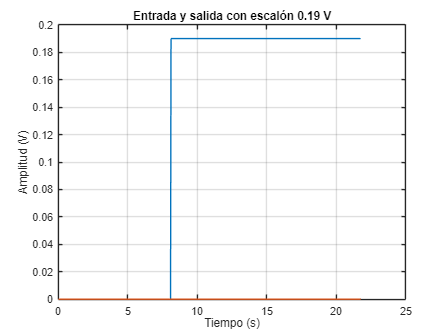

[salida_0_19V, tiempo_0_19V] = representar('./Capturas/Fase1/PGA_G4_0.19V.txt', 0.19, 'V', 0);

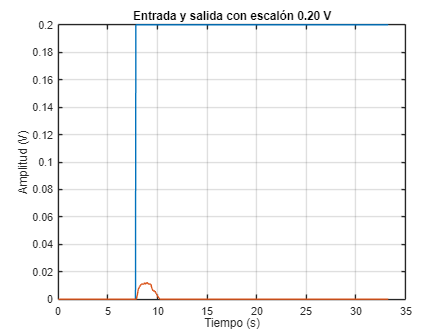

[salida_0_2V, tiempo_0_2V] = representar('./Capturas/Fase1/PGA_G4_0.2V.txt', 0.2, 'V', 0);

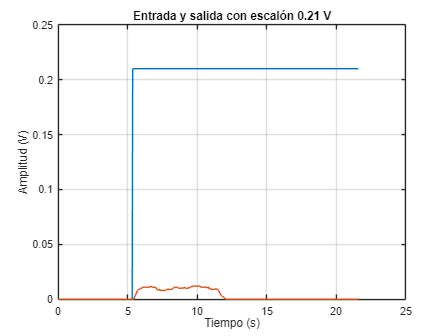

[salida_0_21V, tiempo_0_21V] = representar('./Capturas/Fase1/PGA_G4_0.21V.txt', 0.21, 'V', 0);

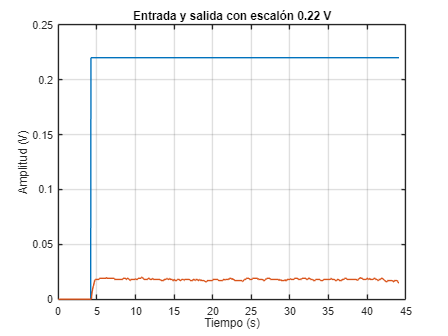

[salida_0_22V, tiempo_0_22V] = representar('./Capturas/Fase1/PGA_G4_0.22V.txt', 0.22, 'V', 0);

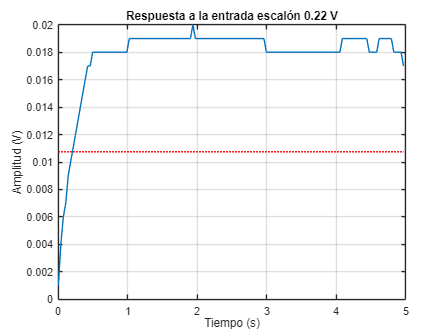

salida(salida_0_22V, tiempo_0_22V, Ts, 0.22, 'V', 0);

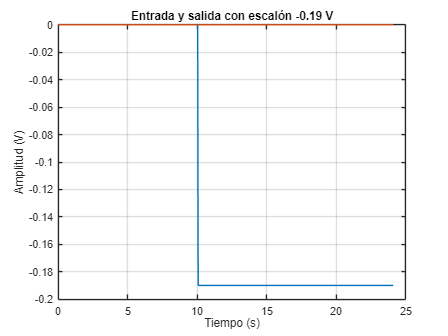

[salida_n0_19V, tiempo_n0_19V] = representar('./Capturas/Fase1/PGA_G4_n0.19V.txt', -0.19, 'V', 0);

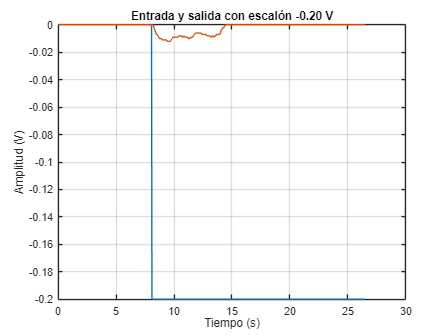

[salida_n0_2V, tiempo_n0_2V] = representar('./Capturas/Fase1/PGA_G4_n0.2V.txt', -0.2, 'V', 0);

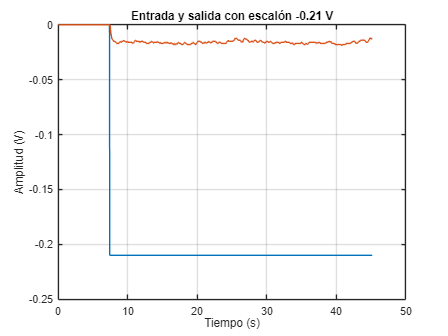

[salida_n0_21V, tiempo_n0_21V] = representar('./Capturas/Fase1/PGA_G4_n0.21V.txt', -0.21, 'V', 0);

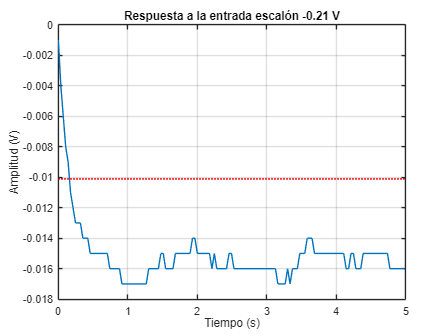

salida(salida_n0_21V, tiempo_n0_21V, Ts, -0.21, 'V', 0);

#### Modelo Simulink:

Entradas positivas:

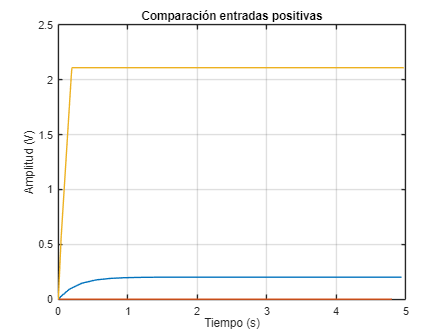

step_value = 1;
[salida_sim_1V, tiempo_sim_1V] = simulink('modeloSatDead', '10');

step_value = 0.21;
[salida_sim_0_21V, tiempo_sim_0_21V] = simulink('modeloSatDead', '10');

step_value = 20;
[salida_sim_20V, tiempo_sim_20V] = simulink('modeloSatDead', '10');

comparacion(salida_sim_1V,tiempo_sim_1V,salida_sim_0_21V,tiempo_sim_0_21V,salida_sim_20V,tiempo_sim_20V,'Comparación entradas positivas')

Entradas negativas:

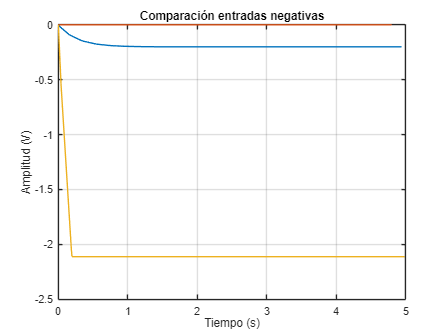

step_value = -1;
[salida_sim_n1V, tiempo_sim_n1V] = simulink('modeloSatDead', '10');

step_value = -0.2;
[salida_sim_n0_2V, tiempo_sim_n0_2V] = simulink('modeloSatDead', '10');

step_value = -20;
[salida_sim_n20V, tiempo_sim_n20V] = simulink('modeloSatDead', '10');

comparacion(salida_sim_n1V,tiempo_sim_n1V,salida_sim_n0_2V,tiempo_sim_n0_2V,salida_sim_n20V,tiempo_sim_n20V,'Comparación entradas negativas')

### Ejercicio 4: Equivalente discreto en régimen permanente y transitorio.

#### Equivalente discreto:

BoG = c2d(Gs, Ts, 'zoh');


$$BoG(z) = \frac{0.0251}{z - 0.8752} [\frac{m/s}{V}]$$


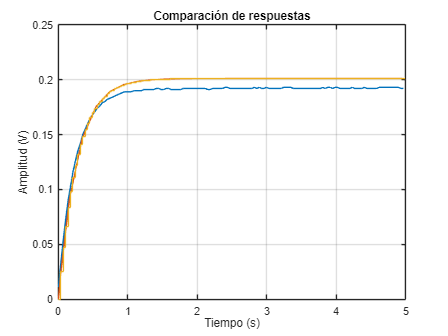

figure;

plot(tiempo_1V,salida_1V);
hold on;
plot(tiempo_sim_1V,salida_sim_1V);
[salida_eq, tiempo_eq] = step(BoG,5);
stairs(tiempo_eq,salida_eq);

hold off;
title('Comparación de respuestas'); 
xlabel('Tiempo (s)'); 
ylabel('Amplitud (V)');
xlim([0 5]);
grid on;

#### Régimen permanente:

La planta es de tipo 0.


$$k_o[BoG] = \lim_{z \to 1} \frac{0.0251}{z - 0.8752} = 0.20112$$


#### Régimen transitorio: 

Polo real simple -> Sistema sobreamortiguado.


$$p = 0.8752$$



$$ks = \frac{-3}{ln(|p|)} = \frac{-3}{ln(0.8752)} = 22.505 = 23$$



$$ts = ks \cdot Ts = 0.805 s$$
 

### Ejercicio 5: Respuesta de la planta en régimen permanente para ±1V con perturbación (10 personas = 700 kg).

En las siguientes capturas, podemos observar como la salida se mantiene normal hasta que se activa la perturbación:

- En el caso de la entrada escalón 1V, se puede ver que cuando se activa la perturbación, como esta vale 0.2V, se resta y la salida es 0V.

- En el caso de la entrada escalón -1V, se puede observar que cuando se activa la perturbación, esta se resta, por lo que la salida vale -0.4V.

Esto tiene sentido dado que cuando las escaleras suben (Tensión positiva), las personas producen una perturbación sustractiva y la escalera necesita más tensión para subir, mientras que cuando las escaleras bajan (Tensión negativa), el peso de las personas aumenta la velocidad de bajada (Obviar la línea en las "Respuesta a la entrada"). 

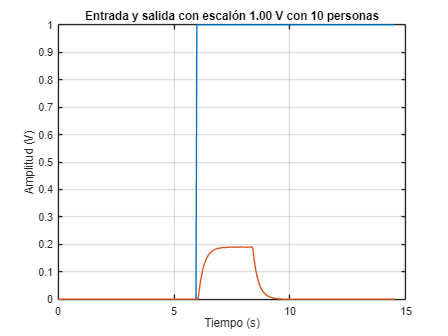

[salida_1V_10P, tiempo_1V_10P] = representar('./Capturas/Fase1/PGA_G4_1V_10P.txt', 1, 'V', 10);

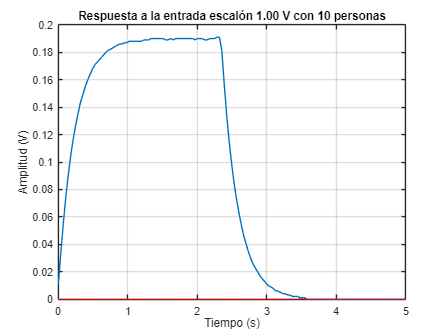

salida(salida_1V_10P, tiempo_1V_10P, Ts, 1, 'V', 10);

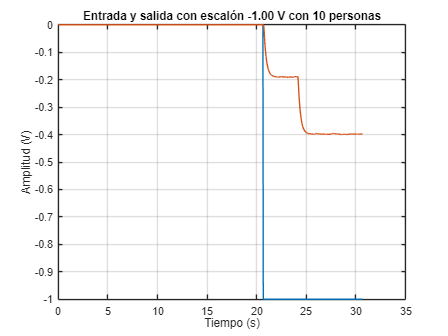

[salida_n1V_10P, tiempo_n1V_10P] = representar('./Capturas/Fase1/PGA_G4_n1V_10P.txt', -1, 'V', 10);

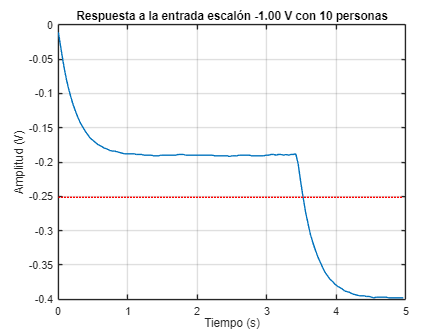

salida(salida_n1V_10P, tiempo_n1V_10P, Ts, -1, 'V', 10);

#### Modelo en Simulink:

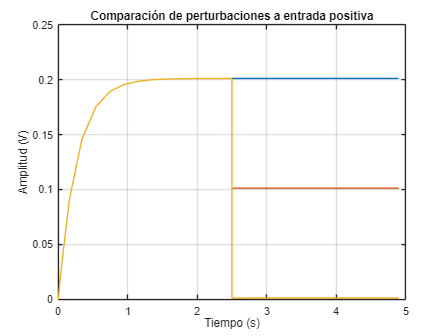

step_value = 1;
pert = 0;
[salida_sim_1V_0P, tiempo_sim_1V_0P] = simulink('modeloPert', '10');

pert = 0.1;
[salida_sim_1V_5P, tiempo_sim_1V_5P] = simulink('modeloPert', '10');

pert = 0.2;
[salida_sim_1V_10P, tiempo_sim_1V_10P] = simulink('modeloPert', '10');

comparacion(salida_sim_1V_0P,tiempo_sim_1V_0P,salida_sim_1V_5P,tiempo_sim_1V_5P,salida_sim_1V_10P,tiempo_sim_1V_10P,'Comparación de perturbaciones a entrada positiva')

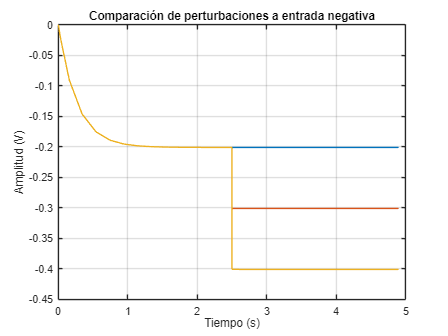

step_value = -1;
pert = 0;
[salida_sim_n1V_0P, tiempo_sim_n1V_0P] = simulink('modeloPert', '10');

pert = 0.1;
[salida_sim_n1V_5P, tiempo_sim_n1V_5P] = simulink('modeloPert', '10');

pert = 0.2;
[salida_sim_n1V_10P, tiempo_sim_n1V_10P] = simulink('modeloPert', '10');

comparacion(salida_sim_n1V_0P,tiempo_sim_n1V_0P,salida_sim_n1V_5P,tiempo_sim_n1V_5P,salida_sim_n1V_10P,tiempo_sim_n1V_10P,'Comparación de perturbaciones a entrada negativa')

# **Fase 2: Diseño directo del regulador**

**Nuevos parámetros iniciales:**

ts = 0.980;
errp = 0.03;


$$BoG(z) = \frac{0.0251}{z - 0.8752} \left[\frac{m/s}{V}\right]$$


### **Ejercicio 6: Calcular la FdeT del regulador con el método directo Truxal.**

**Comprobar si es aplicable (Estabilidad y entrada escalón):**

- Todos los factores del EQD están dentro de la circunferencia unitaria -> Es estable.

- Tiene entrada escalón.

El modelo es **aplicable**.

**Planteamiento del modelo, aplicación de la especificación dinámica:**

ks = ceil(ts/Ts);
fprintf('La ks es: %.4f.\n', ks)
mod_p = exp(-3/ks);
fprintf('El módulo del polo es: %.4f.\n', mod_p)


$$M(z) = \frac{km}{z - 0.8984} \left[\frac{m/s}{m/s}\right]$$


**Chequeo de la causalidad:**


$$gD_{BG} - gN_{BG} \leq gD_M - gN_M$$



$$1 - 0 \leq 1 - 0$$


Se cumple que el regulador es **causal**.

**Aplicación de la especificación estática: **errp = 3%.


$$M(z) = R - errp = 1 - 0.03 = \lim_{z \to 1} \frac{km}{z - 0.8984}$$


km = (1 - errp) * (1 - 0.8984);
fprintf('La km es: %.4f.\n', km)


$$km = 0.0986 \left[\frac{m/s}{m/s}\right]$$


**Modelo final:**

Mz = zpk([],0.8984, 0.0986, Ts);


$$M(z) = \frac{0.0986}{z - 0.8984} \left[\frac{m/s}{m/s}\right]$$



$$N_{BG} = 0.0251; \qquad D_{BG} = z - 0.8752;$$



$$N_M = 0.0986; \qquad D_M = z - 0.8984;$$



$$F(z) = \frac{N_F}{D_F} = \frac{M}{BG \cdot (1 - M)} = \frac{N_M \cdot D_{BG}}{N_{BG} \cdot (D_M - N_M)} = \frac{0.0986z - 0.0863}{0.0251z - 0.0250} \left[\frac{V}{m/s}\right]$$



$$F(z)= \frac{A(z)}{E(z)} =\frac{0.0986 - 0.0863z^{-1}}{0.0251 - 0.0250z^{-1}} = \frac{3.9283 - 3.4382z^{-1}}{1 - 0.9960z^{-1}} \left[\frac{V}{m/s}\right]$$



$$a[k] = 0.9960 \cdot a[k-1] + 3.9283 \cdot e[k] - 3.4382 \cdot e[k - 1]$$


### Ejercicio 7: Dibujar el diagrama de bloques del sistema.

%open_system('diagramaTruxal.slx')

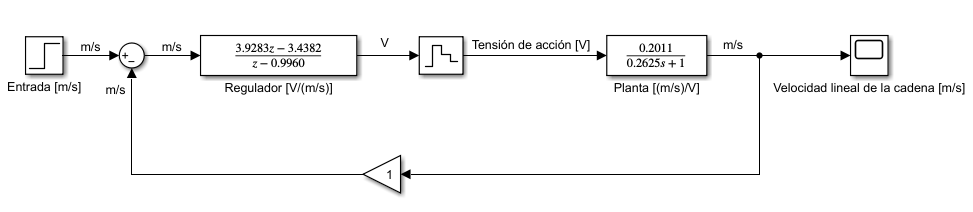

### **Ejercicio 8: Calcular la FdeT del sistema y caracterizar su salida a entradas escalón **±** 1 m/s.**

**FdeT del sistema:**

Fz = tf(minreal(Mz / (BoG * (1 - Mz))));


$$F(z)= \frac{3.928z - 3.438}{z - 0.997} \left[\frac{V}{m/s}\right]$$


Mz = minreal(feedback(series(Fz, BoG), 1));


$$M(z) = \frac{0.0986}{z - 0.8984} \left[\frac{m/s}{m/s}\right]$$


**Entrada escalón +1m/s:**


$$c(\infty) = R \cdot \lim_{z \to 1} \frac{0.0986}{z - 0.8984} = 1 \cdot 0.9705 = 0.9705 m/s$$


**Entrada escalón -1m/s:**


$$c(\infty) = R \cdot \lim_{z \to 1}  \frac{0.0986}{z - 0.8984} = -1 \cdot 0.9705 = -0.9705 m/s$$


### Ejercicio 9: Acción de control y velocidad de la escalera en régimen permanente.

Se ha creado una función "escalera" que realiza las siguientes operaciones:

- Entradas: BoG, Fz, Entrada escalón, Perturbación. 

- Salidas: c(∞) y a(∞).


$$c(\infty) = R \cdot k_0[M(z)_{escalón}] - Perturbación \cdot k_0[M(z)_{perturbación}]$$



$$A(\infty) = \frac{c(\infty) + Perturbacion}{ko[BoG]}$$


**Velocidad de la escalera y Acción de control con 0 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0);

Entrada -1 m/s:

escalera(BoG, Fz, -1, 0);

**Velocidad de la escalera y Acción de control con 5 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0.1);

Entrada -1 m/s:

escalera(BoG, Fz, -1, 0.1);

**Velocidad de la escalera y Acción de control con 10 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0.2);

Entrada -1 m/s:

escalera(BoG, Fz, -1, 0.2);

**Conclusión:**

Cuanto más personas se suben a la escalera, mayor es el peso que ejercen: 

- En el caso de la subida, la señal de acción aumenta dado que se necesita más energía para mover la escalera y que se mantenga constante la velocidad. 

- En el caso de la bajada, cuando mayor es el peso, más facilidad tiene la escalera para bajar, por lo que la señal de control disminuye (en módulo) para que pueda mantenerse constante la velocidad. 

# **Fase 3: Validación del diseño directo**

### **Ejercicio 10: Simulación del sistema de control en simulink.**

%open_system('sistemaTruxal.slx')

**AÑADIR ANÁLISIS EN LA MEMORIA**

### **Ejercicio 11: Características de la respuesta para entrada +1 m/s.**

**Sin carga:**

[salida_1ms_0P, tiempo_1ms_0P] = representar('./Capturas/Fase3/PGA_G4_1ms_0P.txt', 1, 'm/s', 0);
salida(salida_1ms_0P, tiempo_1ms_0P, Ts, 1, 'm/s', 0);

**Con carga - 5 personas:**

[salida_1ms_5P, tiempo_1ms_5P] = representar('./Capturas/Fase3/PGA_G4_1ms_5P.txt', 1, 'm/s', 5);
salida(salida_1ms_5P, tiempo_1ms_5P, Ts, 1, 'm/s', 5);

**Con carga - 10 personas:**

[salida_1ms_10P, tiempo_1ms_10P] = representar('./Capturas/Fase3/PGA_G4_1ms_10P.txt', 1, 'm/s', 10);
salida(salida_1ms_10P, tiempo_1ms_10P, Ts, 1, 'm/s', 10);

### **Ejercicio 12: Características de la respuesta para entrada -1 m/s.**

**Sin carga:**

[salida_n1ms_0P, tiempo_n1ms_0P] = representar('./Capturas/Fase3/PGA_G4_n1ms_0P.txt', -1, 'm/s', 0);
salida(salida_n1ms_0P, tiempo_n1ms_0P, Ts, -1, 'm/s', 0);

**Con carga - 5 personas:**

[salida_n1ms_5P, tiempo_n1ms_5P] = representar('./Capturas/Fase3/PGA_G4_n1ms_5P.txt', -1, 'm/s', 5);
salida(salida_n1ms_5P, tiempo_n1ms_5P, Ts, -1, 'm/s', 5);

**Con carga - 10 personas:**

[salida_n1ms_10P, tiempo_n1ms_10P] = representar('./Capturas/Fase3/PGA_G4_n1ms_10P.txt', -1, 'm/s', 10);
salida(salida_n1ms_10P, tiempo_n1ms_10P, Ts, -1, 'm/s', 10);

### **Ejercicio 13: Régimen permanente de la acción de control y la velocidad de la escalera.**

### **Ejercicio 14: Reflexiones.**

**AÑADIR ANÁLISIS EN LA MEMORIA**

# **Fase 4: Diseño del regulador PID**

**Nuevos parámetros iniciales:**

ts = 1.12;
errp = 0;

Con oscilación nula para entrada escalón.


$$BoG(z) = \frac{0.0251}{z - 0.8752} [\frac{m/s}{V}]$$


### **Ejercicio 15: Calcular la FdeT del regulador PID.**

**Módulo del polo buscado:**

ks = ceil(ts/Ts);
mod_p = exp(-3/ks);
fprintf('El módulo del polo es: %.4f.\n', mod_p)

Como tiene oscilación nula, el polo solo puede estar en el eje real positivo, por lo que:


$$p = 0.9105$$


**Regulador P:**

rlocus(BoG)

No puede ser un regulador P ya que no hay ninguna kp para la que el polo sea el buscado.

**Regulador I:**

Fz = zpk(-1, [0.8752 1], 1, Ts);
rlocus(Fz)

No puede ser un regulador I ya que el polo no sería dominante.

**Regulador PI:**

En primer lugar, el cero elimina el polo no dominante para asegurarnos de que el polo dominante es el que vale lo buscado. Eso se consigue con un regulador:


$$F(z) = K \cdot \frac{z - 0.8752}{z - 1}$$


Ahora falta encontrar el valor de k para el que el polo vale 0.9105. Para ello aplicamos la condición modular:


$$|K| = \frac{1}{|X|} = |\frac{z - 1}{0.0251}| = |\frac{0.9105 - 1}{0.0251}| = 3.5657$$


Finalmente, la función del regulador queda:


$$F(z) = 3.5657 \cdot \frac{z - 0.8752}{z - 1}$$



$$F(z) = \frac{3.5657 - 3.1207z^{-1}}{1 - z^{-1}}$$



$$a[k] = a[k-1] + 3.5657e[k] - 3.1207e[k-1]$$


**Parámetros de sintonía:**


$$Ti = \frac{Ts}{2} \cdot \frac{1 + c}{1 - c} = \frac{0.035}{2} \cdot \frac{1 + 0.8752}{1 - 0.8752} = 0.2629 s$$



$$Kp = K \cdot \frac{2Ti}{2Ti + T} = 3.5657 \cdot \frac{2 \cdot 0.2629}{2 \cdot 0.2629 + 0.035} = 3.3432$$



$$Ki = \frac{Kp}{Ti} = \frac{3.3432}{0.2629} = 12.7166$$



$$q_0 = Kp + \frac{Ki \cdot T}{2} = 3.5657$$



$$q_1 = -Kp + \frac{Ki \cdot T}{2} = -3.1207$$



$$F(z) = \frac{3.5657z^2 - 3.1207z}{z(z - 1)}$$


K = 3.5657;
Ti = (Ts/2) * ((1+0.8752)/(1-0.8752));
Kp = K * (2*Ti)/(2*Ti+Ts);
Ki = Kp/Ti;
q0 = Kp + (Ki*Ts)/2;
q1 = -Kp + (Ki*Ts)/2;
Fz = minreal(tf([q0 q1 0], [1 -1 0], Ts));


$$F(z)= \frac{3.566z - 3.121}{z - 1} \left[\frac{V}{m/s}\right]$$


### Ejercicio 16: Calcular la FdeT del sistema y obtener los polos.

Mz = minreal(feedback(series(Fz, BoG), 1));
pzplot(Mz)
p = pole(Mz);
fprintf('El polo es: %.4f.\n', p)


$$M(z) = \frac{0.0895}{z - 0.9105} \left[\frac{m/s}{m/s}\right]$$


### **Ejercicio 17: Caracterizar en régimen transitorio y permanente la salida a entradas escalón **±** 1 m/s.**

**Regimen permanente:**

Entrada escalón +1m/s:


$$c(\infty) = R \cdot \lim_{z \to 1} \frac{0.0895}{z - 0.9105} = 1 \cdot 1 = 1 m/s$$


Entrada escalón -1m/s:


$$c(\infty) = R \cdot \lim_{z \to 1}  \frac{0.0895}{z - 0.9105} = -1 \cdot 1 = -1 m/s$$


**Régimen transitorio:**

Polo real simple -> Sistema sobreamortiguado.


$$p = 0.9105$$



$$ks = \frac{-3}{ln(|p|)} = \frac{-3}{ln(0.9105)} = 32$$



$$ts = ks \cdot Ts = 1.12 s$$
 

### Ejercicio 18: Acción de control y velocidad de la escalera en régimen permanente para **entradas escalón **±** 1 m/s.**


$$c(\infty) = R \cdot k_0[M(z)_{escalón}] - Perturbación \cdot k_0[M(z)_{perturbación}]$$



$$A(\infty) = \frac{c(\infty) + Perturbacion}{ko[BoG]}$$


**Velocidad de la escalera y Acción de control con 0 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0);

Entrada -1 m/s:

escalera(BoG, Fz, -1, 0);

**Velocidad de la escalera y Acción de control con 5 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0.1);

Entrada -1 m/s:

escalera(BoG, Fz, -1, 0.1);

**Velocidad de la escalera y Acción de control con 10 personas:**

Entrada +1 m/s:

escalera(BoG, Fz, 1, 0.2);

Entrada -1 m/s:

escalera(BoG, Fz, -1, 0.2);

**Conclusión:**

Cuanto más personas se suben a la escalera, mayor es el peso que ejercen: 

- En el caso de la subida, la señal de acción aumenta dado que se necesita más energía para mover la escalera y que se mantenga constante la velocidad. 

- En el caso de la bajada, cuando mayor es el peso, más facilidad tiene la escalera para bajar, por lo que la señal de control disminuye (en módulo) para que pueda mantenerse constante la velocidad. 

# **Fase 5: Validación del regulador PID**

### **Ejercicio 19: Simulación del sistema de control en simulink.**

%simulink

**AÑADIR ANÁLISIS EN LA MEMORIA**

### **Ejercicio 20: Características de la respuesta para entrada +1 m/s.**

**Sin carga:**

[salida_1ms_0P, tiempo_1ms_0P] = representar('./Capturas/Fase5/PGA_G4_1ms_0P.txt', 1, 'm/s', 0);
salida(salida_1ms_0P, tiempo_1ms_0P, Ts, 1, 'm/s', 0);

**Con carga - 5 personas:**

[salida_1ms_5P, tiempo_1ms_5P] = representar('./Capturas/Fase5/PGA_G4_1ms_5P.txt', 1, 'm/s', 5);
salida(salida_1ms_5P, tiempo_1ms_5P, Ts, 1, 'm/s', 5);

**Con carga - 10 personas:**

[salida_1ms_10P, tiempo_1ms_10P] = representar('./Capturas/Fase5/PGA_G4_1ms_10P.txt', 1, 'm/s', 10);
salida(salida_1ms_10P, tiempo_1ms_10P, Ts, 1, 'm/s', 10);

### **Ejercicio 21: Características de la respuesta para entrada -1 m/s.**

**Sin carga:**

[salida_n1ms_0P, tiempo_n1ms_0P] = representar('./Capturas/Fase5/PGA_G4_n1ms_0P.txt', -1, 'm/s', 0);
salida(salida_n1ms_0P, tiempo_n1ms_0P, Ts, -1, 'm/s', 0);

**Con carga - 5 personas:**

[salida_n1ms_5P, tiempo_n1ms_5P] = representar('./Capturas/Fase5/PGA_G4_n1ms_5P.txt', -1, 'm/s', 5);
salida(salida_n1ms_5P, tiempo_n1ms_5P, Ts, -1, 'm/s', 5);

**Con carga - 10 personas:**

[salida_n1ms_10P, tiempo_n1ms_10P] = representar('./Capturas/Fase5/PGA_G4_n1ms_10P.txt', -1, 'm/s', 10);
salida(salida_n1ms_10P, tiempo_n1ms_10P, Ts, -1, 'm/s', 10);

### **Ejercicio 22: Régimen permanente de la acción de control y la velocidad de la escalera.**

### **Ejercicio 23: Reflexiones.**

**AÑADIR ANÁLISIS EN LA MEMORIA**